# Cinéticas de Ozonización

## Experimento 1

Creación de objeto y carga de archivos:

clearvars
close all
clc
exp1 = laiiqatoolbox; % Crea el objeto
exp1.openfiles; % Abre venta de diálogo para seleccionar archivos

### Modificación de parámetros:

exp1.fixedtitle = 'Experimento 1'; % Quitamos el titulo
exp1.xlabel = 'min'; % Unidades de tiempo en minutos para el eje x
exp1.xf{1} = 60; % Delimita los datos hasta 60 min
exp1.legend = {'default'}; % Nombres de leyenda = nombres de archivos

### Creación de gráfico:

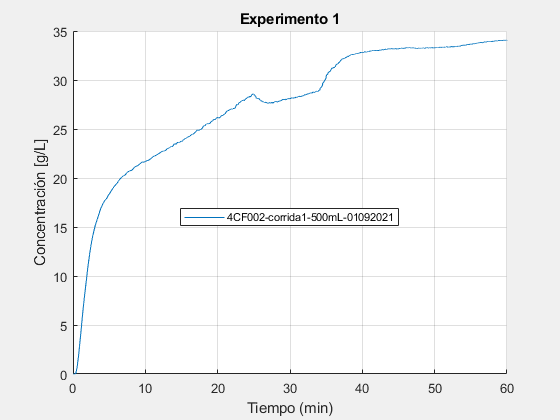

exp1.plotfiles; % Aplica los cambios y crea el objeto gráfico

### Cálculo de consumo de ozono del Experimento 1:

exp1.ozonecalc; % Calcula ozono consumido, residual y total para linea de datos

Para 4CF002-corrida1-500mL-01092021:
    Consumido: 0.40078 g/L
    Residual: 1.6434 g/L
    Total: 2.0442 g/L en 60 min




### Gráfico de consumo de ozono del Experimento 1:

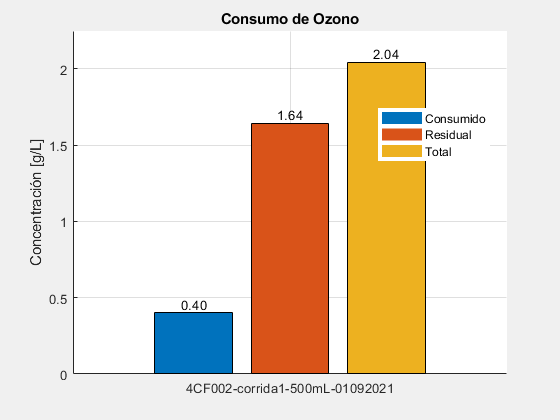

exp1.plotozonecalc;

## Experimento 2

Creación de objeto, carga de archivos y creación de gráfico:

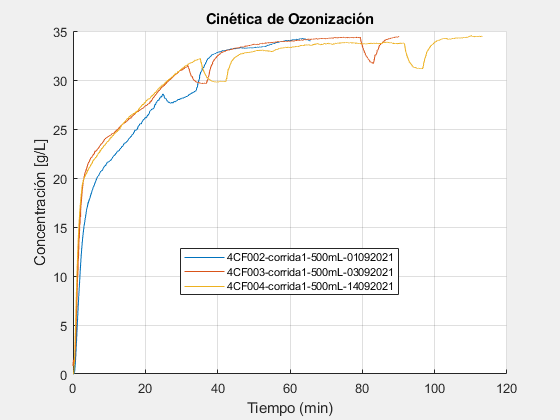

exp2 = laiiqatoolbox;
exp2.openfiles;
exp2.plotfiles;

### Modificación de parámetros:

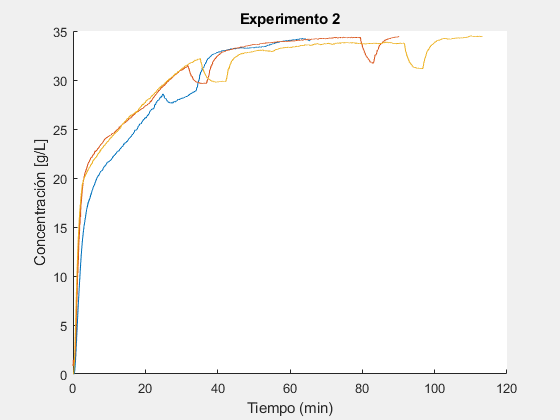

exp2.fixedtitle = 'Experimento 2'; % Cambiamos titulo
exp2.legend = {}; % Desactiva las leyendas en el gráfico
exp2.grid = 'off'; % Quita las rejillas
exp2.LineWidth = 0.8; % Cambiamos el grosor de las líneas. Default = 0.5
exp2.plotfiles; % Aplicamos los cambios

Delimitar todas las lineas de datos a un valor de tiempo máximo:

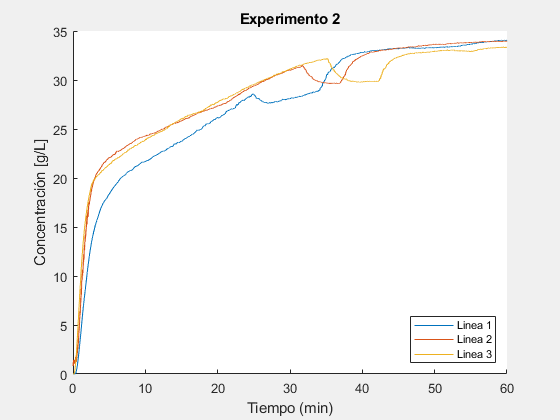

exp2.legend = {'Linea 1' 'Linea 2' 'Linea 3'}; % Restauramos las leyendas
% con nuevos nombres (para motivos de este ejemplo)
exp2.xf = {60 60 60}; % Delimitamos todos los datos a 60 minutos
exp2.plotfiles; % Aplicamos los cambios

Para el Experimento 2 se tienen 3 lineas de datos, modificamos la **Linea 1** y **2** para ajustarlas a la caida de concentración de la **Linea 3**:

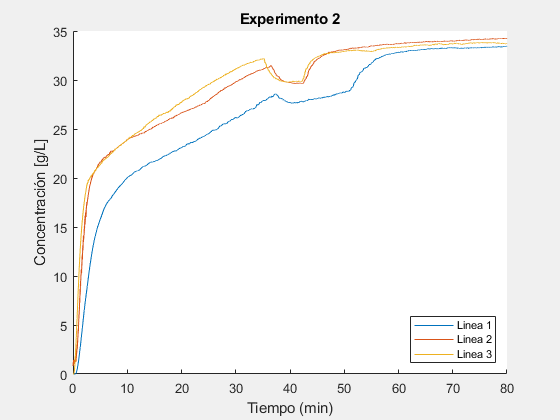

exp2.xlabel = 'min'; % Primero establecemos las unidades de tiempo a modificar
exp2.xf = {'end' 'end' 'end'}; % Luego establecemos los valores por default de xf
exp2.xk = {1.5 1.15 1}; % Aumentamos el tiempo de la Linea 1 en un 50%, Linea 2 un 15% 
% y Linea 3 sin aumentar, ya que no es  necesario
exp2.xf = {80 80 80}; % Cortamos los datos de todas las lineas a 80 minutos máximo (opcional)
exp2.plotfiles; % Aplicamos los cambios

Guardado de figuras:

exp1.imageResolution = 800; % Resolución de la imagen de la figura 1 
% default = 300. Solo aplica para imagenes NO vectoriales.
exp2.imageResolution = 600; % Resolución de la imagen de la figura 2
exp2.fixedtitle = ''; % Quitamos el titulo de la figura 2 dejando vacías las comillas cencillas
exp1.saveplot('MiExperimento1.png'); % Nombre y extensión de figura 1

exp2.saveplot('MiExperimento2.png'); % Guardado de figura 2

Cálculo de ozono del **Experimento 2**:

exp2.ozonecalc;

Para Linea 1:
    Consumido: 0.55067 g/L
    Residual: 2.1269 g/L
    Total: 2.6776 g/L en 80 min


Para Linea 2:
    Consumido: 0.38828 g/L
    Residual: 2.3525 g/L
    Total: 2.7408 g/L en 80 min


Para Linea 3:
    Consumido: 0.3302 g/L
    Residual: 2.3766 g/L
    Total: 2.7068 g/L en 80 min




Gráfico de consumo de ozono del **Experimento 2**.

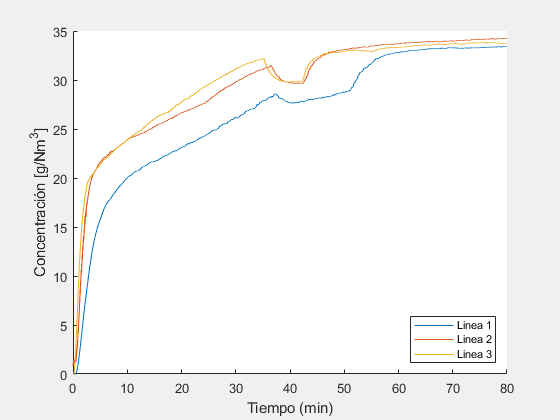

exp2.ozoneUnits = 'g/Nm^3'; % Cambiamos las unidades de concentración 
% de ozono. Default = 'g/L'
exp2.plotfiles; % Aplicamos los cambios

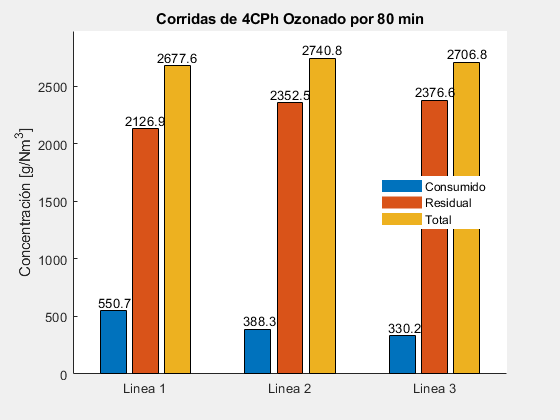

exp2.ozonetitle = 'Corridas de 4CPh Ozonado por 80 min'; % Titulo del gráfico de barras
exp2.plotozonecalc;